fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt',...
    '../fabio_data/dhpc09_cnmfe.mat');

nreps = 80;
[mean_err_shuf, mean_err_auto] = deal(zeros(nreps,1));
WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    ss_res = fs_sess.decode_spikeshuf(false);
    mean_err_shuf(i) = mean(ss_res.dec_error_spikeshuf);
    ss_res_auto = fs_sess.decode_spikeshuf(true);
    mean_err_auto(i) = mean(ss_res_auto.dec_error_spikeshuf);
    WaitMessage.Send;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).


WaitMessage.Destroy;

save stef_fig_save.mat mean_err_auto mean_err_shuf fs_sess nreps

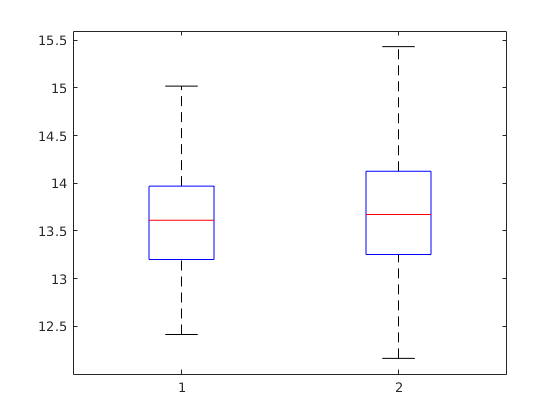

figure;
boxplot([mean_err_auto mean_err_shuf]);

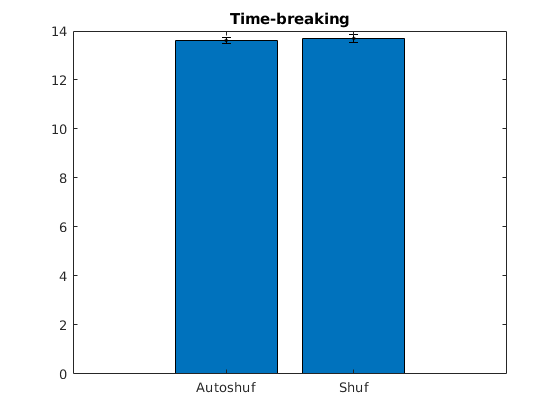

figure;
errnbar([mean(mean_err_auto) mean(mean_err_shuf)], 1.96.*[sem(mean_err_auto) sem(mean_err_shuf)]);
set(gca, 'XTickLabels', {'Autoshuf', 'Shuf'});
title 'Time-breaking'

t_ = tic;
nreps = 80;
WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    res(i) = fs_sess.decode_all;
    WaitMessage.Send;
end
WaitMessage.Destroy;
toc(t_)

Elapsed time is 6125.907122 seconds.


save stef_fig_save_res.mat res fs_sess

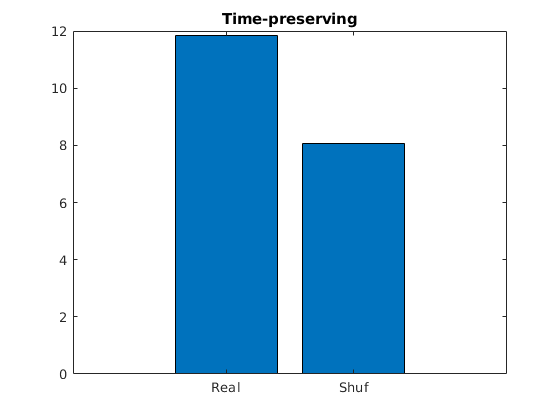

figure;
bar([mean(res.dec_error_real), mean(res.dec_error_shuf)]);
set(gca, 'XTickLabels', {'Real', 'Shuf'});
title 'Time-preserving'

## Testing

fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt',...
    '../fabio_data/dhpc09_cnmfe.mat');

S = full(fs_sess.spike_traces.');
trim_mobile = @(s) s(fs_sess.mobile, :);
Sm = trim_mobile(S);
Xm = trim_mobile(fs_sess.convolve_data(S));

[~, ks_raw] = fs_sess.discrete_pos;
Sm_shuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile));
Sm_autoshuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true));

Xm_shuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile)));
Xm_autoshuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true)));

[X_cont, y_cont, ks, X_spikeshuf, X_spikeshuf_auto] = fs_sess.get_continuous_dataset;

## Trying without convolution

Decoding without convolution

OpenField.decode_all_general(Sm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.4598
    fs_metric_shuf_mean: 17.4076
    fs_metric_diag_mean: 18.0216


Decoding without convolution, label-shuffle

OpenField.decode_all_general(Sm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 20.1556
    fs_metric_shuf_mean: 20.6778
    fs_metric_diag_mean: 19.7925


Sanity check: decoding a pre-shuffled input, without convolution

OpenField.decode_all_general(Sm_shuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.9739
    fs_metric_shuf_mean: 18.9319
    fs_metric_diag_mean: 17.5764


Sanity check: decodng a pre-autoshuffled input, without convolution

OpenField.decode_all_general(Sm_autoshuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.7507
    fs_metric_shuf_mean: 17.4492
    fs_metric_diag_mean: 17.9476


Results summary without convolution:

Original = Shuffle-within > Shuffle (in terms of error)

## Trying with convolution

Plain

OpenField.decode_all_general(Xm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 9.6746
    fs_metric_shuf_mean: 6.6322
    fs_metric_diag_mean: 10.6089


label-shuffle

OpenField.decode_all_general(Xm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 20.1848
    fs_metric_shuf_mean: 21.1145
    fs_metric_diag_mean: 20.6535


Sanity check: decoding a pre-shuffled input

OpenField.decode_all_general(Xm_shuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 13.7812
    fs_metric_shuf_mean: 6.5237
    fs_metric_diag_mean: 13.8959


Sanity check: decodng a pre-autoshuffled input

OpenField.decode_all_general(Xm_autoshuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 11.3357
    fs_metric_shuf_mean: 6.3606
    fs_metric_diag_mean: 10.6543


nreps = 20;
WaitMessage = parfor_wait(nreps*2);
for i = 1:nreps
    megares_conv(i) = real_soc_cos(fs_sess, true);
    WaitMessage.Send;
    megares_noconv(i) = real_soc_cos(fs_sess, false);
    WaitMessage.Send;
end

Getting data...Decoding real... Done in 40.2761 s
Decoding cos... Done in 40.3377 s
Decoding coas... Done in 39.4488 s
Decoding soc... Done in 37.5401 s
Decoding asoc... Done in 42.4239 s
Decoding labelshuf... Done in 42.6099 s


2.50%; 247.46s used and 0.00s needed...


Getting data...Decoding real... Done in 39.0247 s
Decoding cos... Done in 39.56 s
Decoding coas... Done in 39.5997 s
Decoding soc... Done in 42.9615 s
Decoding asoc... Done in 38.898 s
Decoding labelshuf... Done in 39.4516 s


5.00%; 491.67s used and 9279.89s needed...


Getting data...Decoding real... Done in 39.6095 s
Decoding cos... Done in 38.6675 s
Decoding coas... Done in 38.5955 s
Decoding soc... Done in 39.4268 s
Decoding asoc... Done in 41.4609 s
Decoding labelshuf... Done in 42.8007 s


7.50%; 736.91s used and 9073.88s needed...


Getting data...Decoding real... Done in 39.2508 s
Decoding cos... Done in 37.211 s
Decoding coas... Done in 40.895 s
Decoding soc... Done in 34.9937 s
Decoding asoc... Done in 40.5466 s
Decoding labelshuf... Done in 38.7719 s


10.00%; 973.30s used and 8509.88s needed...


Getting data...Decoding real... Done in 40.0725 s
Decoding cos... Done in 36.2129 s
Decoding coas... Done in 41.8467 s
Decoding soc... Done in 36.7806 s
Decoding asoc... Done in 40.8494 s
Decoding labelshuf... Done in 42.4472 s


12.50%; 1216.16s used and 8500.36s needed...


Getting data...Decoding real... Done in 39.8591 s
Decoding cos... Done in 36.3568 s
Decoding coas... Done in 41.8617 s
Decoding soc... Done in 36.0867 s
Decoding asoc... Done in 42.8074 s
Decoding labelshuf... Done in 42.8089 s


15.00%; 1460.62s used and 8311.68s needed...


Getting data...Decoding real... Done in 39.3252 s
Decoding cos... Done in 37.3307 s
Decoding coas... Done in 41.3174 s
Decoding soc... Done in 38.531 s
Decoding asoc... Done in 41.0079 s
Decoding labelshuf... Done in 42.5809 s


17.50%; 1705.41s used and 8077.80s needed...


Getting data...Decoding real... Done in 36.8748 s
Decoding cos... Done in 37.3901 s
Decoding coas... Done in 42.3316 s
Decoding soc... Done in 35.7833 s
Decoding asoc... Done in 40.6859 s
Decoding labelshuf... Done in 38.7143 s


20.00%; 1941.95s used and 7569.55s needed...


Getting data...Decoding real... Done in 40.2675 s
Decoding cos... Done in 35.7924 s
Decoding coas... Done in 40.8835 s
Decoding soc... Done in 39.0823 s
Decoding asoc... Done in 41.4988 s
Decoding labelshuf... Done in 43.2712 s


22.50%; 2187.42s used and 7609.36s needed...


Getting data...Decoding real... Done in 38.9828 s
Decoding cos... Done in 37.956 s
Decoding coas... Done in 42.239 s
Decoding soc... Done in 37.2544 s
Decoding asoc... Done in 39.3591 s
Decoding labelshuf... Done in 39.5945 s


25.00%; 2427.47s used and 7201.53s needed...


Getting data...Decoding real... Done in 39.4664 s
Decoding cos... Done in 41.1299 s
Decoding coas... Done in 40.4564 s
Decoding soc... Done in 38.8013 s
Decoding asoc... Done in 42.1266 s
Decoding labelshuf... Done in 42.1464 s


27.50%; 2676.30s used and 7216.25s needed...


Getting data...Decoding real... Done in 40.149 s
Decoding cos... Done in 35.4744 s
Decoding coas... Done in 39.2582 s
Decoding soc... Done in 36.7728 s
Decoding asoc... Done in 39.569 s
Decoding labelshuf... Done in 38.5576 s


30.00%; 2910.72s used and 6563.62s needed...


Getting data...Decoding real... Done in 39.7049 s
Decoding cos... Done in 38.2524 s
Decoding coas... Done in 42.2617 s
Decoding soc... Done in 39.0206 s
Decoding asoc... Done in 42.1437 s
Decoding labelshuf... Done in 42.3823 s


32.50%; 3159.16s used and 6707.84s needed...


Getting data...Decoding real... Done in 39.2327 s
Decoding cos... Done in 39.8154 s
Decoding coas... Done in 40.8461 s
Decoding soc... Done in 39.8385 s
Decoding asoc... Done in 41.6386 s
Decoding labelshuf... Done in 40.1156 s


35.00%; 3405.60s used and 6407.39s needed...


Getting data...Decoding real... Done in 39.9125 s
Decoding cos... Done in 37.9739 s
Decoding coas... Done in 39.53 s
Decoding soc... Done in 38.5013 s
Decoding asoc... Done in 41.8793 s
Decoding labelshuf... Done in 42.4578 s


37.50%; 3650.51s used and 6122.91s needed...


Getting data...Decoding real... Done in 39.8497 s
Decoding cos... Done in 38.2513 s
Decoding coas... Done in 42.0185 s
Decoding soc... Done in 36.5977 s
Decoding asoc... Done in 39.6714 s
Decoding labelshuf... Done in 40.7553 s


40.00%; 3892.55s used and 5808.99s needed...


Getting data...Decoding real... Done in 39.5937 s
Decoding cos... Done in 36.4531 s
Decoding coas... Done in 40.1733 s
Decoding soc... Done in 39.0235 s
Decoding asoc... Done in 40.9016 s
Decoding labelshuf... Done in 43.3866 s


42.50%; 4136.75s used and 5616.46s needed...


Getting data...Decoding real... Done in 40.3303 s
Decoding cos... Done in 37.099 s
Decoding coas... Done in 42.2199 s
Decoding soc... Done in 40.1009 s
Decoding asoc... Done in 40.3873 s
Decoding labelshuf... Done in 41.3177 s


45.00%; 4382.84s used and 5414.08s needed...


Getting data...Decoding real... Done in 39.629 s
Decoding cos... Done in 40.8637 s
Decoding coas... Done in 41.4625 s
Decoding soc... Done in 40.038 s
Decoding asoc... Done in 41.902 s
Decoding labelshuf... Done in 42.957 s


47.50%; 4634.53s used and 5285.35s needed...


Getting data...Decoding real... Done in 39.0702 s
Decoding cos... Done in 35.0675 s
Decoding coas... Done in 41.5963 s
Decoding soc... Done in 38.2195 s
Decoding asoc... Done in 41.9468 s
Decoding labelshuf... Done in 38.2012 s


50.00%; 4873.28s used and 4775.15s needed...


Getting data...Decoding real... Done in 40.0646 s
Decoding cos... Done in 39.6033 s
Decoding coas... Done in 39.5179 s
Decoding soc... Done in 37.6904 s
Decoding asoc... Done in 41.071 s
Decoding labelshuf... Done in 41.3473 s


52.50%; 5117.23s used and 4635.08s needed...


Getting data...Decoding real... Done in 40.2836 s
Decoding cos... Done in 41.2569 s
Decoding coas... Done in 40.6212 s
Decoding soc... Done in 37.8428 s
Decoding asoc... Done in 41.4952 s
Decoding labelshuf... Done in 40.7448 s


55.00%; 5364.11s used and 4443.83s needed...


Getting data...Decoding real... Done in 40.9107 s
Decoding cos... Done in 39.8516 s
Decoding coas... Done in 39.2858 s
Decoding soc... Done in 39.3014 s
Decoding asoc... Done in 42.4775 s
Decoding labelshuf... Done in 43.7521 s


57.50%; 5614.54s used and 4257.25s needed...


Getting data...Decoding real... Done in 40.3066 s
Decoding cos... Done in 42.6954 s
Decoding coas... Done in 43.0855 s
Decoding soc... Done in 40.4377 s
Decoding asoc... Done in 41.5892 s
Decoding labelshuf... Done in 42.1053 s


60.00%; 5869.48s used and 4079.05s needed...


Getting data...Decoding real... Done in 39.3152 s
Decoding cos... Done in 38.134 s
Decoding coas... Done in 40.4465 s
Decoding soc... Done in 39.9129 s
Decoding asoc... Done in 42.124 s
Decoding labelshuf... Done in 42.7739 s


62.50%; 6116.86s used and 3710.61s needed...


Getting data...Decoding real... Done in 40.5772 s
Decoding cos... Done in 37.9841 s
Decoding coas... Done in 42.7161 s
Decoding soc... Done in 37.7925 s
Decoding asoc... Done in 40.3275 s
Decoding labelshuf... Done in 38.955 s


65.00%; 6359.93s used and 3403.08s needed...


Getting data...Decoding real... Done in 40.1602 s
Decoding cos... Done in 40.2671 s
Decoding coas... Done in 40.5056 s
Decoding soc... Done in 39.2066 s
Decoding asoc... Done in 41.9838 s
Decoding labelshuf... Done in 44.2276 s


67.50%; 6611.01s used and 3263.99s needed...


Getting data...Decoding real... Done in 38.5392 s
Decoding cos... Done in 39.144 s
Decoding coas... Done in 38.2941 s
Decoding soc... Done in 37.3873 s
Decoding asoc... Done in 40.6318 s
Decoding labelshuf... Done in 41.3372 s


70.00%; 6851.06s used and 2880.58s needed...


Getting data...Decoding real... Done in 40.6941 s
Decoding cos... Done in 38.4632 s
Decoding coas... Done in 42.0703 s
Decoding soc... Done in 39.205 s
Decoding asoc... Done in 41.2386 s
Decoding labelshuf... Done in 43.052 s


72.50%; 7100.47s used and 2743.56s needed...


Getting data...Decoding real... Done in 39.5571 s
Decoding cos... Done in 41.7078 s
Decoding coas... Done in 41.6557 s
Decoding soc... Done in 38.7192 s
Decoding asoc... Done in 40.8068 s
Decoding labelshuf... Done in 37.4401 s


75.00%; 7345.19s used and 2447.18s needed...


Getting data...Decoding real... Done in 39.667 s
Decoding cos... Done in 40.2121 s
Decoding coas... Done in 42.3219 s
Decoding soc... Done in 40.6385 s
Decoding asoc... Done in 42.4889 s
Decoding labelshuf... Done in 43.7381 s


77.50%; 7598.97s used and 2283.99s needed...


Getting data...Decoding real... Done in 39.2257 s
Decoding cos... Done in 37.2357 s
Decoding coas... Done in 43.2308 s
Decoding soc... Done in 38.4268 s
Decoding asoc... Done in 43.7667 s
Decoding labelshuf... Done in 39.8113 s


80.00%; 7845.35s used and 1971.09s needed...


Getting data...Decoding real... Done in 40.0206 s
Decoding cos... Done in 37.3104 s
Decoding coas... Done in 40.8752 s
Decoding soc... Done in 38.2003 s
Decoding asoc... Done in 41.5463 s
Decoding labelshuf... Done in 43.0702 s


82.50%; 8091.09s used and 1720.19s needed...


Getting data...Decoding real... Done in 40.0077 s
Decoding cos... Done in 37.3986 s
Decoding coas... Done in 41.3547 s
Decoding soc... Done in 35.9149 s
Decoding asoc... Done in 40.835 s
Decoding labelshuf... Done in 40.237 s


85.00%; 8331.52s used and 1442.54s needed...


Getting data...Decoding real... Done in 39.7267 s
Decoding cos... Done in 38.4424 s
Decoding coas... Done in 38.809 s
Decoding soc... Done in 41.4991 s
Decoding asoc... Done in 41.9212 s
Decoding labelshuf... Done in 42.3187 s


87.50%; 8579.01s used and 1237.46s needed...


Getting data...Decoding real... Done in 39.4165 s
Decoding cos... Done in 38.741 s
Decoding coas... Done in 40.3131 s
Decoding soc... Done in 37.5518 s
Decoding asoc... Done in 39.6155 s
Decoding labelshuf... Done in 38.973 s


90.00%; 8818.29s used and 957.13s needed...


Getting data...Decoding real... Done in 39.6572 s
Decoding cos... Done in 35.6994 s
Decoding coas... Done in 38.7639 s
Decoding soc... Done in 38.4681 s
Decoding asoc... Done in 42.5538 s
Decoding labelshuf... Done in 42.6415 s


92.50%; 9060.80s used and 727.52s needed...


Getting data...Decoding real... Done in 39.3824 s
Decoding cos... Done in 38.7186 s
Decoding coas... Done in 39.9371 s
Decoding soc... Done in 38.0665 s
Decoding asoc... Done in 44.2053 s
Decoding labelshuf... Done in 39.0132 s


95.00%; 9304.83s used and 488.05s needed...


Getting data...Decoding real... Done in 39.7602 s
Decoding cos... Done in 37.8774 s
Decoding coas... Done in 44.3406 s
Decoding soc... Done in 39.3002 s
Decoding asoc... Done in 41.9785 s
Decoding labelshuf... Done in 42.6249 s


97.50%; 9555.39s used and 250.56s needed...


Getting data...Decoding real... Done in 39.1853 s
Decoding cos... Done in 35.1616 s
Decoding coas... Done in 42.5363 s
Decoding soc... Done in 37.4543 s
Decoding asoc... Done in 40.258 s
Decoding labelshuf... Done in 40.0249 s


100.00%; 9794.64s used and 0.00s needed...


WaitMessage.Destroy;
save stef_fig_save_megares.mat megares_conv megares_noconv fs_sess

bp = comp_struct(megares_conv);
bp.real = bp.real(1:10);
bp_noconv = comp_struct(megares_noconv);
bp_noconv.real = bp_noconv.real(1:10);

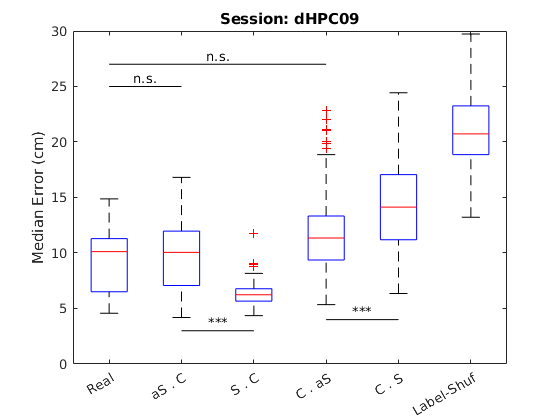

figure;
signif_multibox({bp.real, bp.asoc, bp.soc, bp.coas, bp.cos, bp.labelshuf},...
    {'Real', 'aS . C', 'S . C', 'C . aS', 'C . S', 'Label-Shuf'},...
    {{'Real', 'aS . C'}, {'Real', 'C . aS'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
    [25 27 3 4], 0.75);
ylim([0 30]);
ylabel 'Median Error (cm)'
title 'Session: dHPC09'

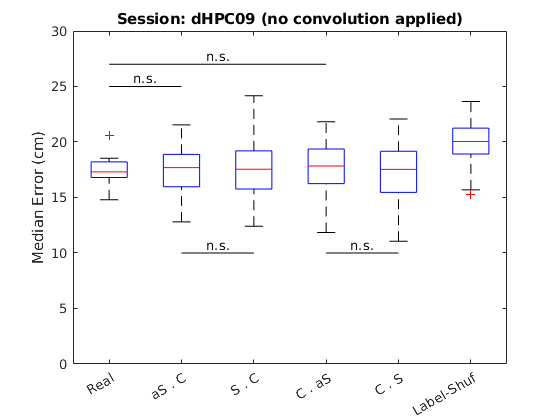

figure;
signif_multibox({bp_noconv.real, bp_noconv.asoc, bp_noconv.soc, bp_noconv.coas, bp_noconv.cos, bp_noconv.labelshuf},...
    {'Real', 'aS . C', 'S . C', 'C . aS', 'C . S', 'Label-Shuf'},...
    {{'Real', 'aS . C'}, {'Real', 'C . aS'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
    [25 27 10 10], 0.75);
ylim([0 30]);
ylabel 'Median Error (cm)'
title 'Session: dHPC09 (no convolution applied)'

t_ = tic;
res_linear = our_results(69, true) % was with 2.2 tau

res_linear = struct with fields:
    real: 3.5899
     soc: 2.3991
     cos: 7.6142
    coas: 5.2553


toc(t_)

Elapsed time is 282.786089 seconds.


t_ = tic;
res_linear = our_results(69, true) % with 0.5 tau

res_linear = struct with fields:
    real: 3.0011
     soc: 1.8159
     cos: 4.7008
    coas: 4.0916


toc(t_)

Elapsed time is 276.301329 seconds.


t_ = tic;
res_linear = our_results(69, true) % with 0.5 tau

res_linear = struct with fields:
    real: 3.0288
     soc: 1.9758
     cos: 4.5537
    coas: 4.0648


toc(t_)

Elapsed time is 274.672285 seconds.


WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    res_linear(i) = our_results(69, true); % with our exact gamma/alpha function
    WaitMessage.Send;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).
Analyzing and transferring files to the workers ...done.


WaitMessage.Destroy;

bp_lin.real = [res_linear.real].';
bp_lin.inshuf = [res_linear.inshuf].';
bp_lin.asoc = [res_linear.asoc].';
bp_lin.soc = [res_linear.soc].';
bp_lin.coas = [res_linear.coas].';
bp_lin.cos = [res_linear.cos].';

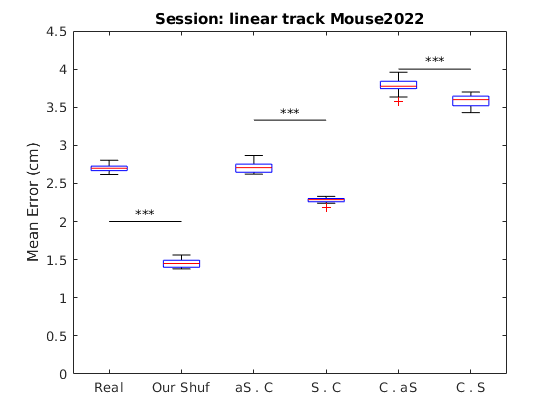

figure;
signif_multibox({bp_lin.real, bp_lin.inshuf, bp_lin.asoc, bp_lin.soc, bp_lin.coas, bp_lin.cos},...
    {'Real', 'Our Shuf', 'aS . C', 'S . C', 'C . aS', 'C . S'},...
    {{'Real', 'Our Shuf'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
    [2, 3.33, 4], 0.1);
ylim([0 4.5]);
ylabel 'Mean Error (cm)'
title 'Session: linear track Mouse2022'

t_ = tic;
res_linear_no_conv = our_results(69, false) % with NO tau

res_linear_no_conv = struct with fields:
      real: 7.6764
    inshuf: 5.3944
       cos: 7.0940
      coas: 8.9946
       soc: 6.8460
      asoc: 8.8944


toc(t_)

Elapsed time is 521.318438 seconds.


t_ = tic;
res_linear_with_conv = our_results(69, true) % with our tau

res_linear_with_conv = struct with fields:
      real: 2.7119
    inshuf: 1.4675
       cos: 3.5955
      coas: 3.8158
       soc: 2.2769
      asoc: 2.7164


toc(t_)

Elapsed time is 474.643953 seconds.


usable_idx = 69;
sm = SessManager;
d = sm.cons_usable(usable_idx);
load(d.source_path);
S = tracesEvents.HD_spikes;
pos = tracesEvents.position;

[r_asoc, X_asoc, ks_asoc] = get_lin_res(S, pos, true, false, true);
r_asoc

r_asoc = 2.7772

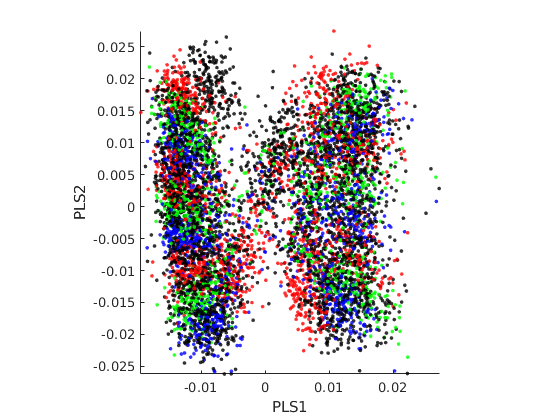

see_pls(X_asoc, ks_asoc);

[r_soc, X_soc, ks_soc] = get_lin_res(S, pos, true, false, false);
r_soc

r_soc = 2.2493

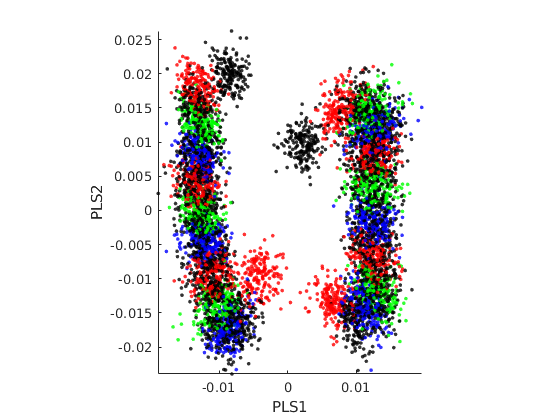

see_pls(X_soc, ks_soc);

[r_coas, X_coas, ks_coas] = get_lin_res(S, pos, true, true, true);
r_coas

r_coas = 3.7982

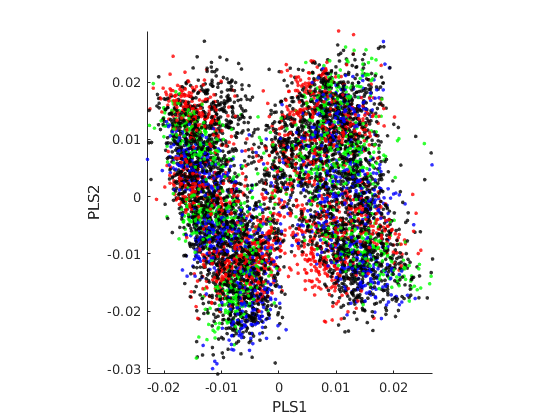

see_pls(X_coas, ks_coas);

[r_cos, X_cos, ks_cos] = get_lin_res(S, pos, true, true, false);
r_cos

r_cos = 3.5122

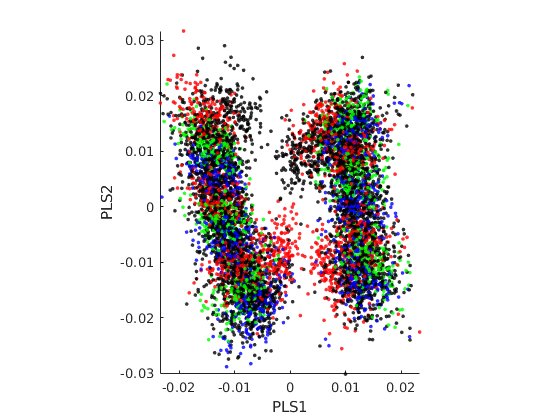

see_pls(X_cos, ks_cos);

t_ = tic;
mres_ = real_soc_cos(fs_sess, true)

Getting data...Decoding real...Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).
 Done in 67.6647 s
Decoding cos... Done in 44.2571 s
Decoding coas... Done in 39.5353 s
Decoding soc... Done in 37.0445 s
Decoding asoc... Done in 41.3253 s
Decoding labelshuf... Done in 42.3835 s


mres_ = struct with fields:
         real: [10×1 double]
          cos: [10×1 double]
         coas: [10×1 double]
          soc: [10×1 double]
         asoc: [10×1 double]
    labelshuf: [10×1 double]


toc(t_)

Elapsed time is 277.003991 seconds.


function s_out = comp_struct(s_in)
F = fields(s_in);
for i = 1:numel(F)
    f = F{i};
    s_out.(f) = vertcat(s_in.(f));
end
end

function megares = real_soc_cos(fs_sess, with_conv)
S = full(fs_sess.spike_traces.');
trim_mobile = @(s) s(fs_sess.mobile, :);

if ~with_conv
    Xm = trim_mobile(S);
else
    Xm = trim_mobile(fs_sess.convolve_data(S));
end

[~, ks_raw] = fs_sess.discrete_pos;

ksm = -ks_raw.*(-1).^fs_sess.mobile;
if ~with_conv
    Xm_cos  = @() trim_mobile(fshuffle(S, ksm, false));
    Xm_coas = @() trim_mobile(fshuffle(S, ksm, true ));
    
    Xm_soc  = @() trim_mobile(fshuffle(S, ksm, false));
    Xm_asoc = @() trim_mobile(fshuffle(S, ksm, true ));
else
    Xm_cos  = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, ksm, false)));
    Xm_coas = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, ksm, true )));
    
    Xm_soc  = @() trim_mobile(fshuffle(fs_sess.convolve_data(S), ksm, false));
    Xm_asoc = @() trim_mobile(fshuffle(fs_sess.convolve_data(S), ksm, true ));
end

fprintf('Getting data...');
[~, y_cont, ks] = fs_sess.get_continuous_dataset;

fprintf('Decoding real...');
t_ = tic;
res = OpenField.decode_all_general(Xm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.real = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));

fprintf('Decoding cos...');
t_ = tic;
res = OpenField.decode_all_general(Xm_cos(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.cos = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));

fprintf('Decoding coas...');
t_ = tic;
res = OpenField.decode_all_general(Xm_coas(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.coas = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));

fprintf('Decoding soc...');
t_ = tic;
res = OpenField.decode_all_general(Xm_soc(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.soc = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));

fprintf('Decoding asoc...');
t_ = tic;
res = OpenField.decode_all_general(Xm_asoc(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.asoc = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));

fprintf('Decoding labelshuf...');
t_ = tic;
res = OpenField.decode_all_general(Xm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims);
megares.labelshuf = res.fs_metric_real;
fprintf(' Done in %g s\n', toc(t_));
end

function res = our_results(usable_idx, with_conv)
bin_width = 5.9;
tau = 0.5; %2.2
fps = 20;
sm = SessManager;
d = sm.cons_usable(usable_idx);
load(d.source_path);
S = tracesEvents.HD_spikes;
if with_conv
    C = tau_conv(S, tau, fps);
else
    C = S;
end

opt = DecodeTensor.default_opt;
[~, ~, tr_s, tr_e, tr_dir, tr_bins, tr_dir_bins] = DecodeTensor.new_sel(tracesEvents.position(:,1), opt);
data_tensor = DecodeTensor.construct_tensor(C, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.real = err_res.mean_err.unshuffled;
res.inshuf = err_res.mean_err.shuffled;

within_trial = false(size(tr_dir_bins));
for i = 1:numel(tr_s)
    within_trial(tr_s(i):tr_e(i)) = true;
end

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, false);
if with_conv
    C_shuf = tau_conv(S_shuf, tau, fps);
else
    C_shuf = S_shuf;
end
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.cos = err_res.mean_err.unshuffled;

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, true);
if with_conv
    C_shuf = tau_conv(S_shuf, tau, fps);
else
    C_shuf = S_shuf;
end
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.coas = err_res.mean_err.unshuffled;


%% now shuffle post

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;

if with_conv
    C = tau_conv(S, tau, fps);
else
    C = S;
end
C_shuf = fshuffle(C, tr_dir_bins_intrial, false);

data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.soc = err_res.mean_err.unshuffled;

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
if with_conv
    C = tau_conv(S, tau, fps);
else
    C = S;
end
C_shuf = fshuffle(C, tr_dir_bins_intrial, true);
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.asoc = err_res.mean_err.unshuffled;

end

function [r, Xd, ksd] = get_lin_res(S, pos, with_conv, shuf_before, auto)
bin_width = 5.9;
tau = 0.5; %2.2
fps = 20;

opt = DecodeTensor.default_opt;
[~, ~, tr_s, tr_e, tr_dir, tr_bins, tr_dir_bins] = DecodeTensor.new_sel(pos(:,1), opt);


within_trial = false(size(tr_dir_bins));
for i = 1:numel(tr_s)
    within_trial(tr_s(i):tr_e(i)) = true;
end

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;

X = S;
if shuf_before
    X = fshuffle(X, tr_dir_bins_intrial, auto);
end
if with_conv
    X = tau_conv(X, tau, fps);
end
if ~shuf_before
    X = fshuffle(X, tr_dir_bins_intrial, auto);
end

data_tensor = DecodeTensor.construct_tensor(X, tr_bins, opt.n_bins, tr_s, tr_e);

%err_res = DecodeTensor.decode_all(data_tensor, tr_dir, bin_width, my_algs('ecoclin'), [], []);
%r = err_res.mean_err.unshuffled;
r = DecodeTensor.decode_tensor(data_tensor, tr_dir, bin_width, my_algs('ecoclin'), false, [], []);
[Xd, ksd] = DecodeTensor.tensor2dataset(data_tensor, tr_dir);
end

function C = tau_conv_fs(S, tau, fps)
S = S.';

n_frame_div = tau * fps;
assert(n_frame_div > 0);
transient = exp(-(0:50)/n_frame_div);
C = conv2(S, transient, 'full');
C = C(:, 1:size(S,2));

C = C.';
end

function C = tau_conv(S, ~, ~)
T = 1.5;
Fs = 20;
gamma_sample_times = linspace(0,7.5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma = @(t) t.*exp(1-t);
transient_profile = gamma(gamma_sample_times);
transient_profile = transient_profile(:);
C = conv2(S, transient_profile, 'full');
C = C(1:size(S,1),:);
end

function see_pls(X, ks)
alpha = 0.8;
X_z = zscore(X);
[XS, stats, origin] = ...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
xlabel PLS1
ylabel PLS2
axis equal
axis tight
end